# K_PhaseWave_demo.mlx

Status: Done

See also

`K_PhaseWave, K_PhaseWave_test, K_plotLinearPhaseWave`

# Load and prepare data

clear; close all; clc;
[basedir,homedir,~,~,resdir] = setup();


load(fullfile(resdir, 'chanSpec_eegpow_lfppow_act_actdelta.mat')); %chanSpec

chanSpec = changepathplatform(chanSpec,basedir);


TFact = chanSpec.isact;
TFactdelta = chanSpec.isactdelta;
TFchan_eeg = chanSpec.ischan_EEG;
TFchan_probeA00h = chanSpec.ischan_probeA00h;
TFchan_BZ = chanSpec.ischan_BZ;
TFchan_CZ = chanSpec.ischan_CZ;

TFmat_BZCZ = chanSpec.ismatparentofchan(TFchan_BZ) & ...
    chanSpec.ismatparentofchan(TFchan_CZ);


## find a neuron with max ratioBeta in their LFP


chanSpec_target = chanSpec.choose((TFact | TFactdelta) & TFchan_BZ & TFchan_probeA00h);

S = chanSpec_target.getstructNby1('ratioBeta');

[B,I]= sort([S(:).ratioBeta],'descend');
B(1:3)

ans =     0.1917    0.1912    0.1891


I(1:3)

ans =     84    86    85


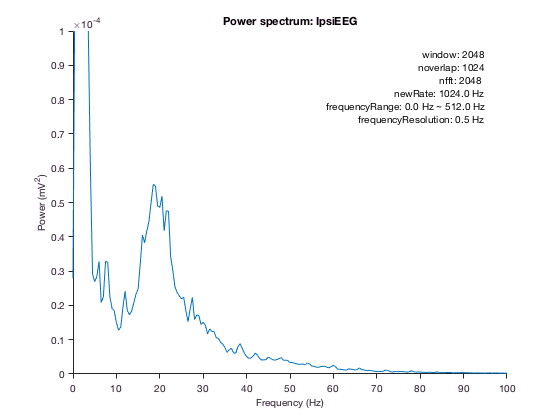

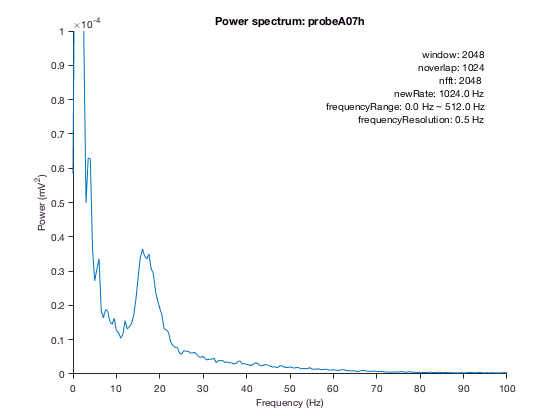

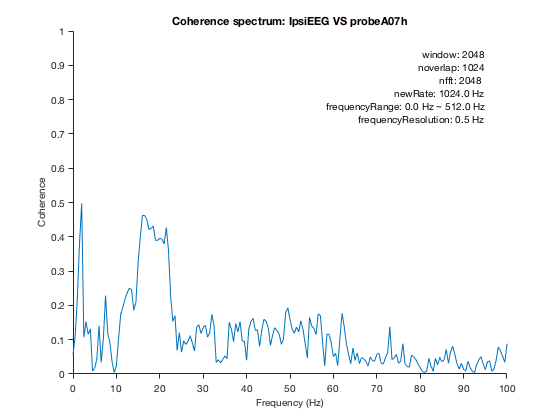

[matname1,eeg1,wide1] = local_getChan(chanSpec,S,I(1));

matname1

matname1 = 'kjx140e01@300-400_m'

eeg1.ChanTitle

ans = 'IpsiEEG'

wide1.ChanTitle

ans = 'probeA07h'

wide1.Header.location

ans = 'BZ'

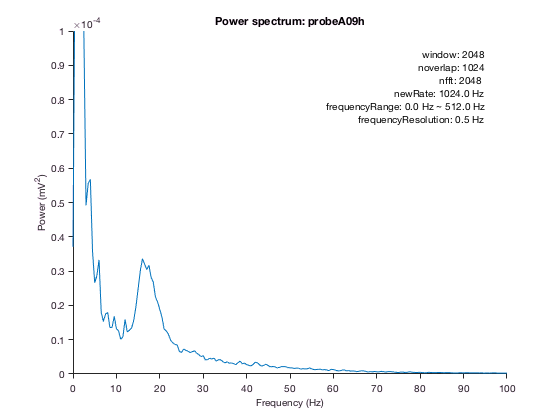

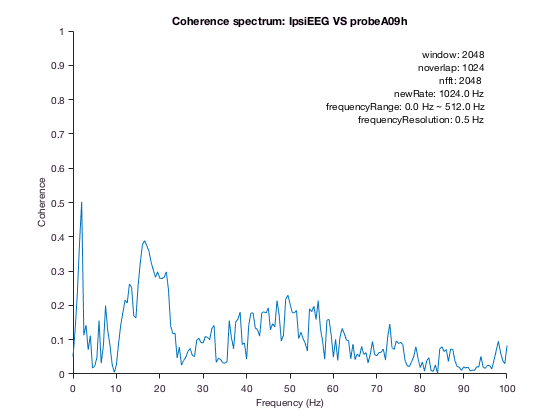

[matname2,eeg2,wide2] = local_getChan(chanSpec,S,I(2));

matname2

matname2 = 'kjx140e01@300-400_m'

eeg2.ChanTitle

ans = 'IpsiEEG'

wide2.ChanTitle

ans = 'probeA09h'

wide2.Header.location

ans = 'BZ'

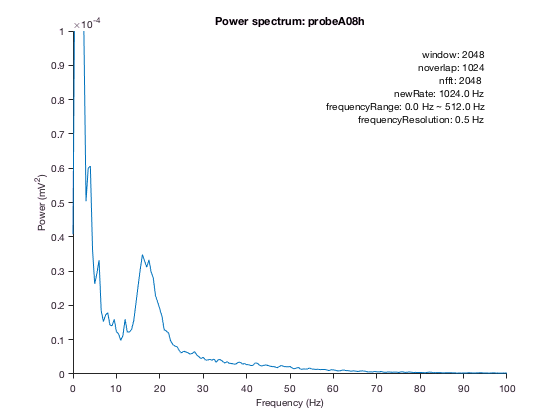

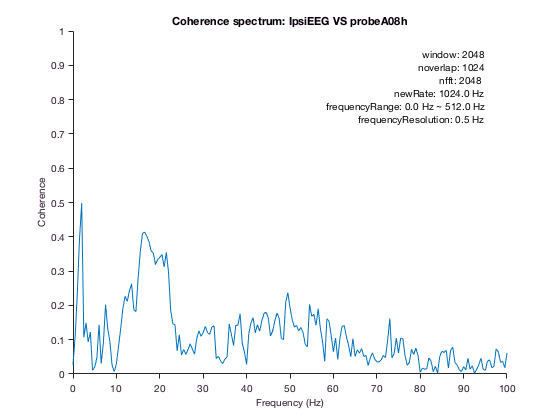

[matname3,eeg3,wide3] = local_getChan(chanSpec,S,I(3));

matname3

matname3 = 'kjx140e01@300-400_m'

eeg3.ChanTitle

ans = 'IpsiEEG'

wide3.ChanTitle

ans = 'probeA08h'

wide3.Header.location

ans = 'BZ'

BUA preparation

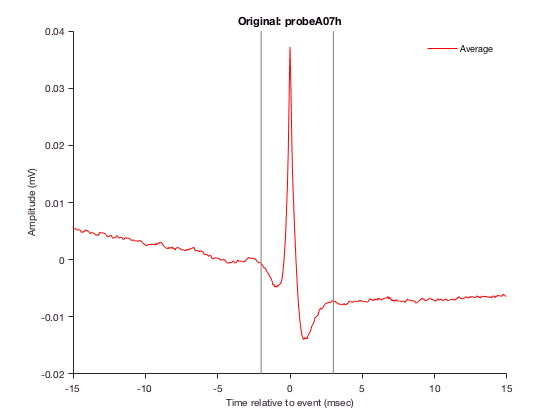

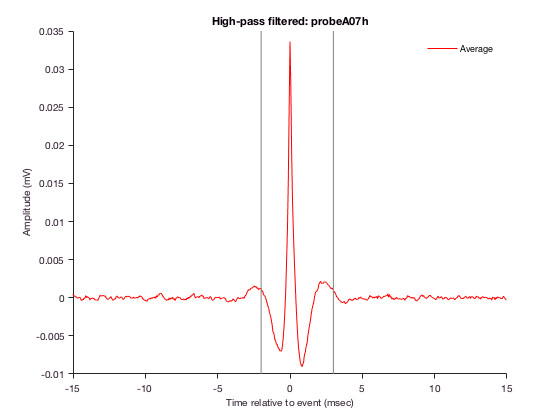

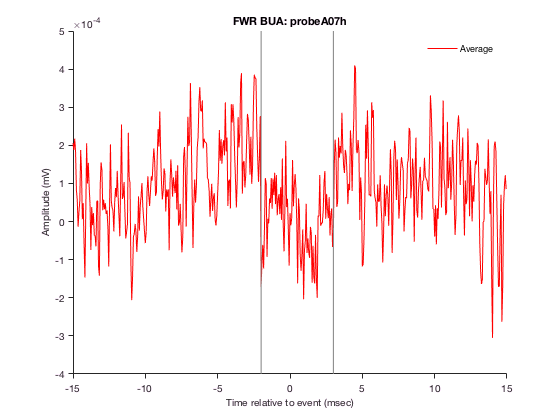

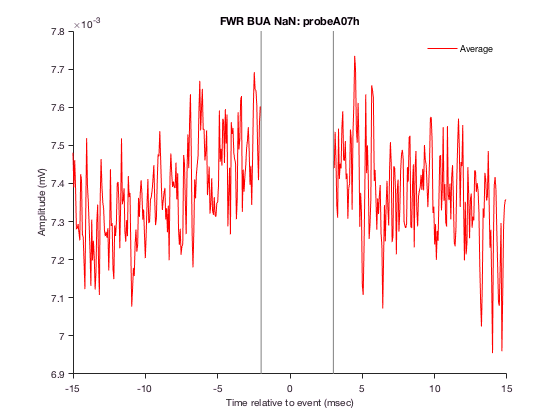

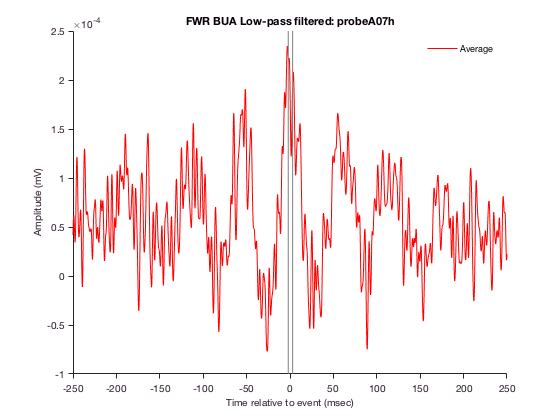

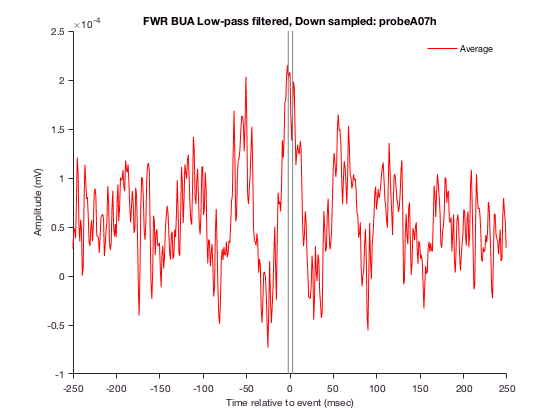

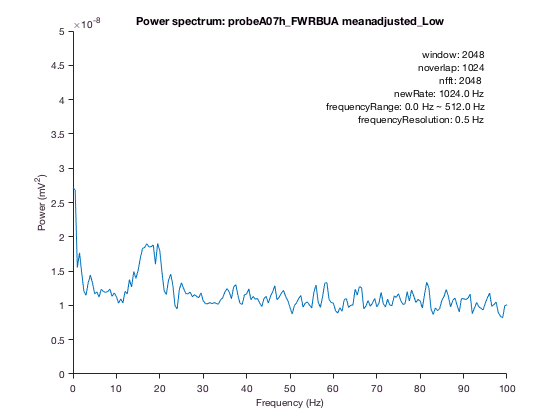

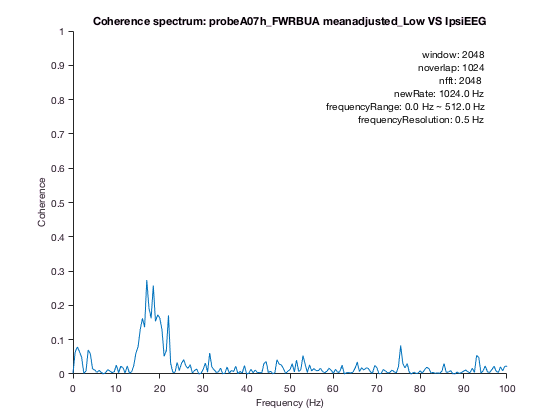

[eeg1L,lfp1L,bua1L] = local_getEEGLFPBUA(eeg1,wide1);

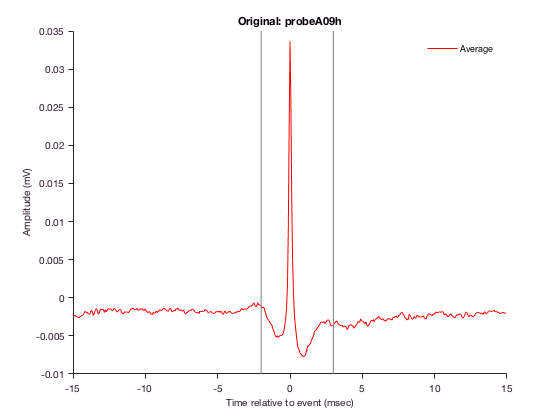

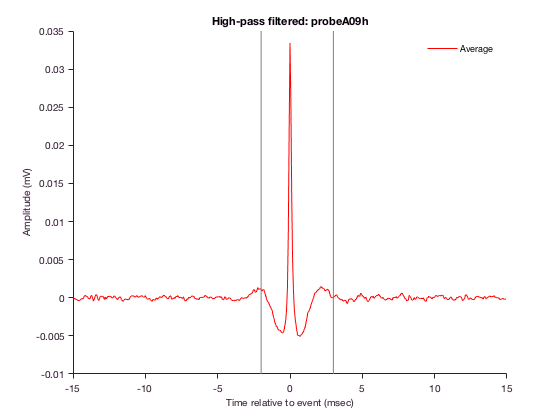

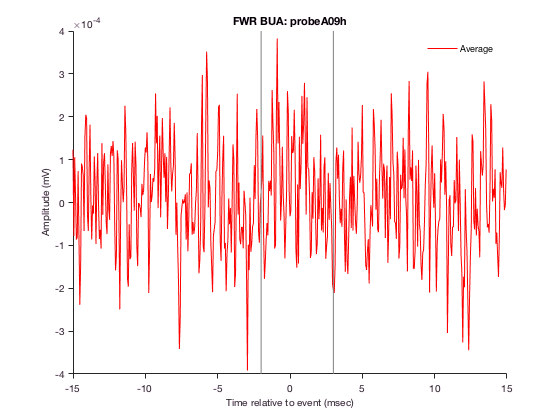

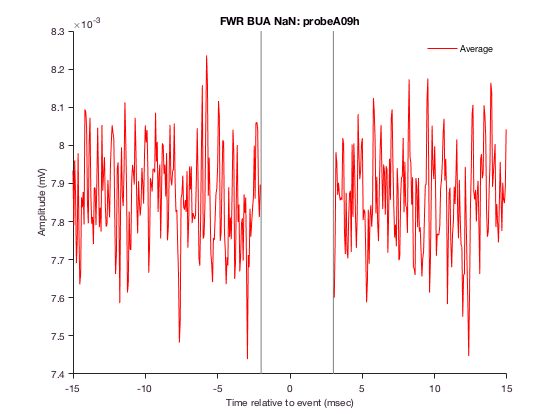

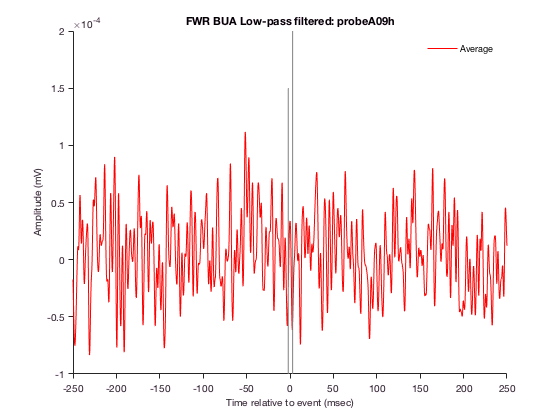

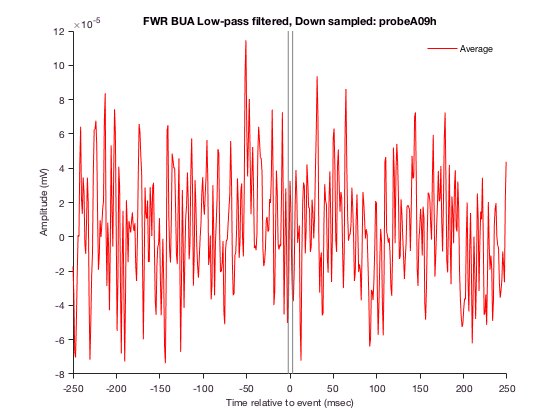

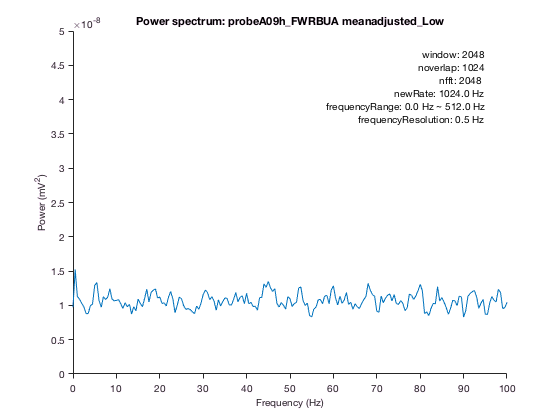

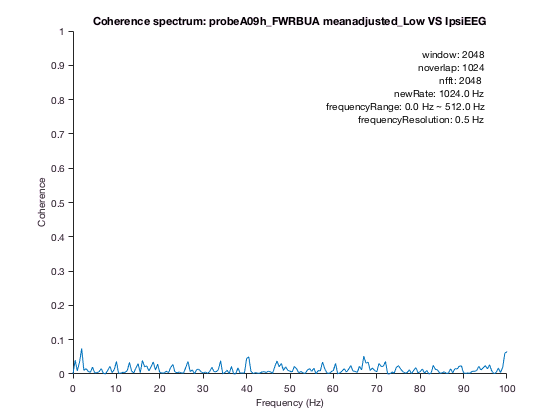

[eeg2L,lfp2L,bua2L] = local_getEEGLFPBUA(eeg2,wide2);

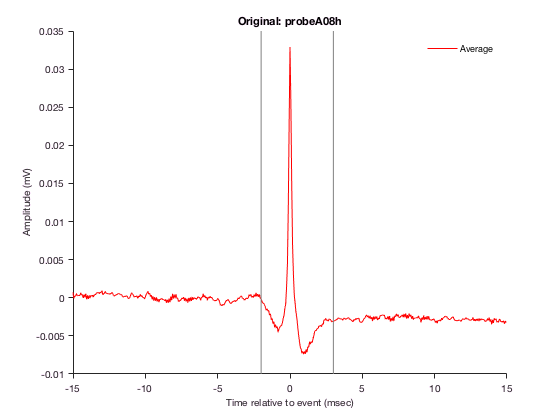

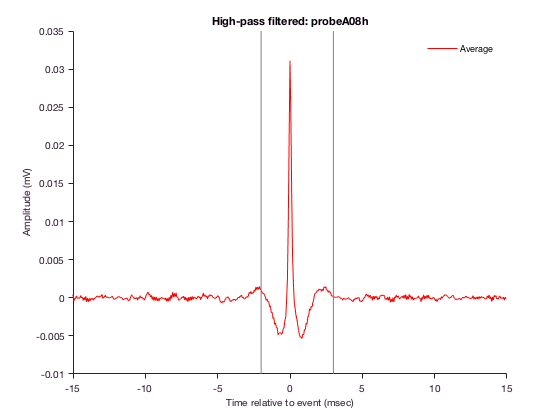

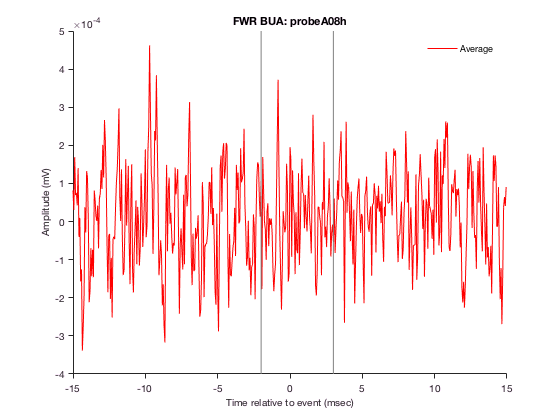

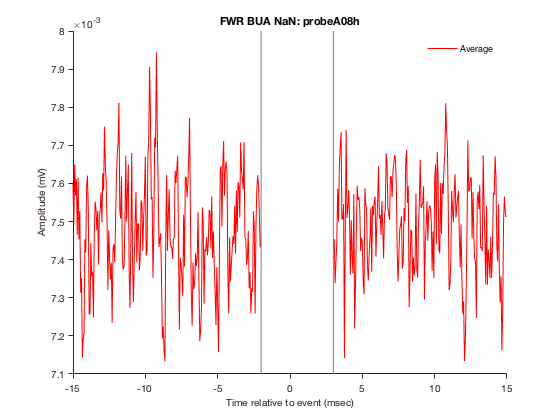

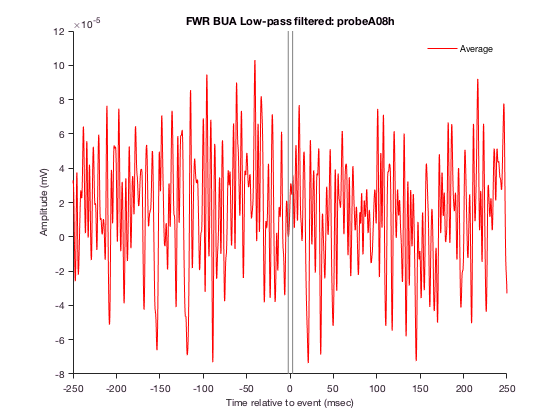

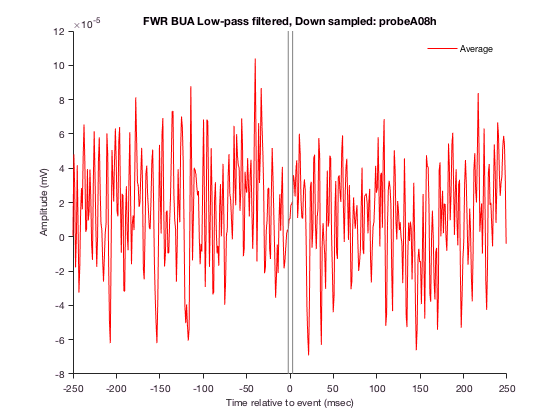

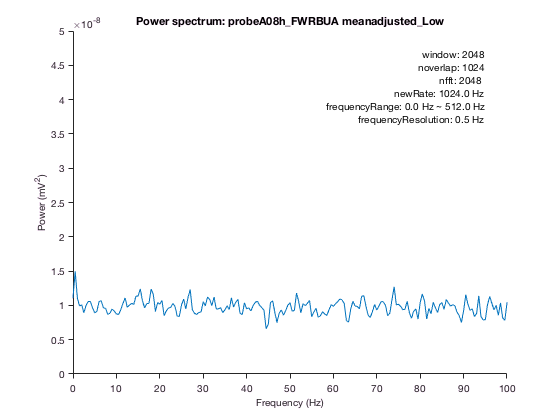

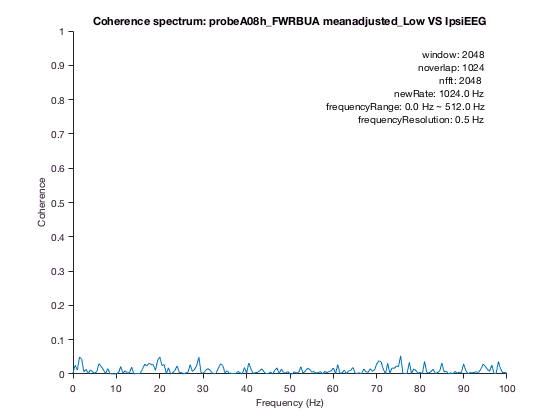

[eeg3L,lfp3L,bua3L] = local_getEEGLFPBUA(eeg3,wide3);

# `K_PhaseWave` without Bootstrap

Wn = normalizedfreq([13 30],1024);
[b, a] = butter(3, Wn,'bandpass');
% fvtool(b,a,'Fs',newRate);
% xlim([0 5]);ylim('auto');
assert(isstable(b,a));

**flip LFP (but not BUA) for polarity**

results = struct with fields:
      binmean: [72×1 double]
       binstd: [72×1 double]
       binsem: [72×1 double]
        axrad: [72×1 double]
      meanvec: [1×1 struct]
    bootstrap: [1×1 struct]
    circshift: [1×1 struct]


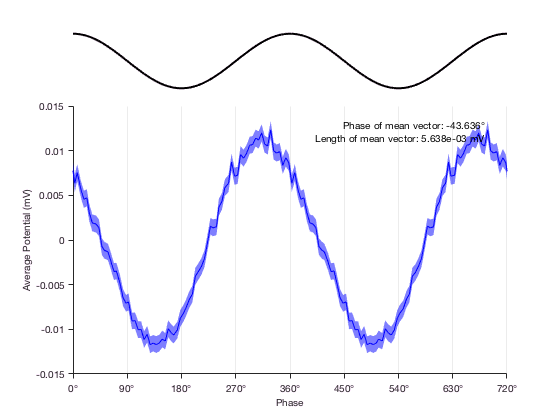

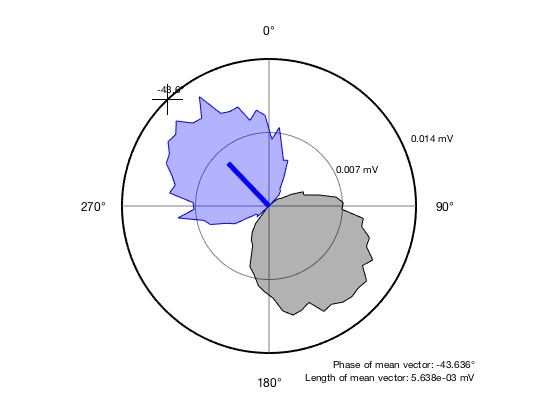


results = K_PhaseWave(-lfp1L.Data,eeg1L.Data,1024,1024,b,a,'randomization','none',...
    'plotLinear',true,'plotCirc',true)


fprintf('Vector length is only %.1f%% of SD of data\n',results.meanvec.length/std(-lfp1L.Data)*100)

Vector length is only 15.5% of SD of data


**BUA**

results = struct with fields:
      binmean: [72×1 double]
       binstd: [72×1 double]
       binsem: [72×1 double]
        axrad: [72×1 double]
      meanvec: [1×1 struct]
    bootstrap: [1×1 struct]
    circshift: [1×1 struct]


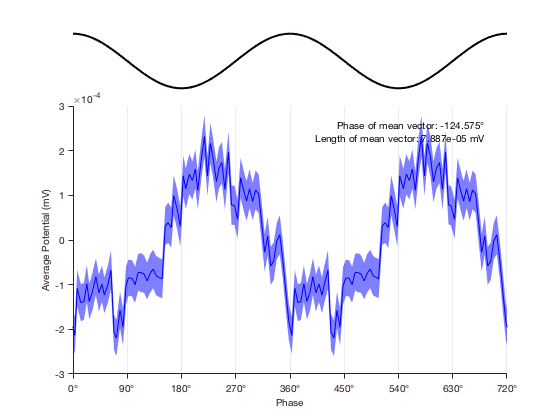

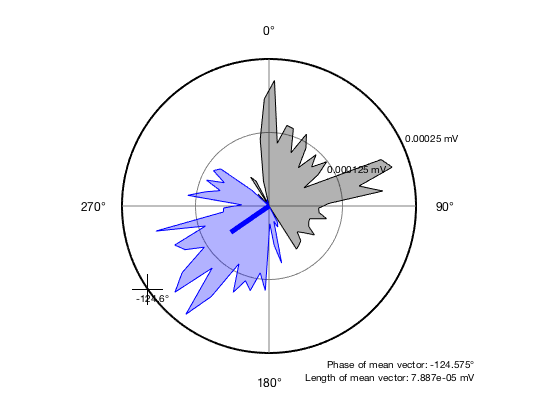

results = K_PhaseWave(bua1L.Data,eeg1L.Data,1024,1024,b,a,'randomization','none',...
    'plotLinear',true,'plotCirc',true)


fprintf('Vector length is only %.1f%% of SD of data\n',results.meanvec.length/std(bua1L.Data)*100)

Vector length is only 4.8% of SD of data


`hbin` = 36 seems all right for `bar`

ans = struct with fields:
      binmean: [36×1 double]
       binstd: [36×1 double]
       binsem: [36×1 double]
        axrad: [36×1 double]
      meanvec: [1×1 struct]
    bootstrap: [1×1 struct]
    circshift: [1×1 struct]


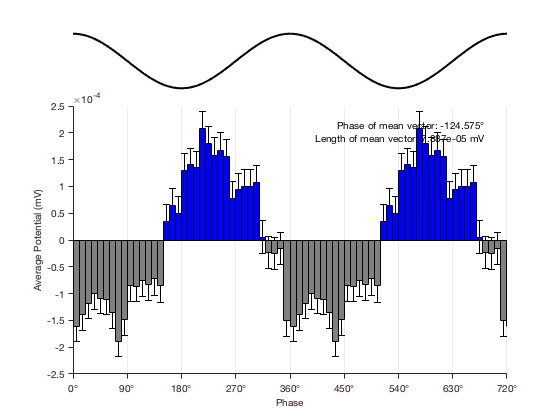

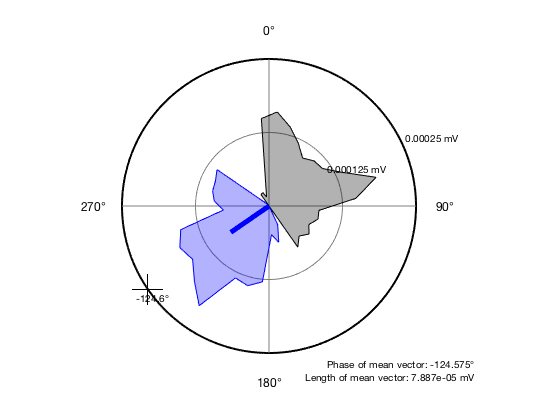

K_PhaseWave(bua1L.Data,eeg1L.Data,1024,1024, b, a,'randomization','none',...
    'histtype','bar','histbin',36,...
    'plotLinear',true,'plotCirc',true)

ans = struct with fields:
      binmean: [72×1 double]
       binstd: [72×1 double]
       binsem: [72×1 double]
        axrad: [72×1 double]
      meanvec: [1×1 struct]
    bootstrap: [1×1 struct]
    circshift: [1×1 struct]


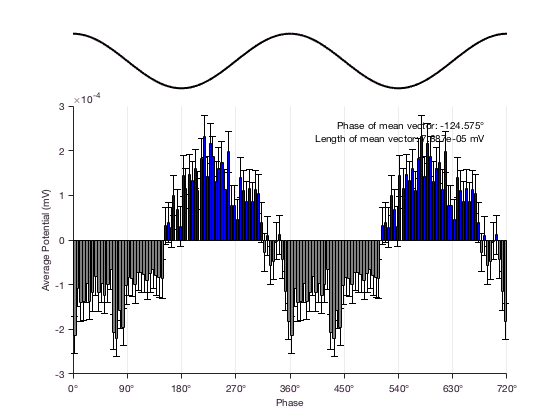

K_PhaseWave(bua1L.Data,eeg1L.Data,1024,1024, b, a,'randomization','none',...
    'histtype','bar','histbin',72,...
    'plotLinear',true,'plotCirc',true)

# plot One neuron with `K_plotLinearPhaseWave`

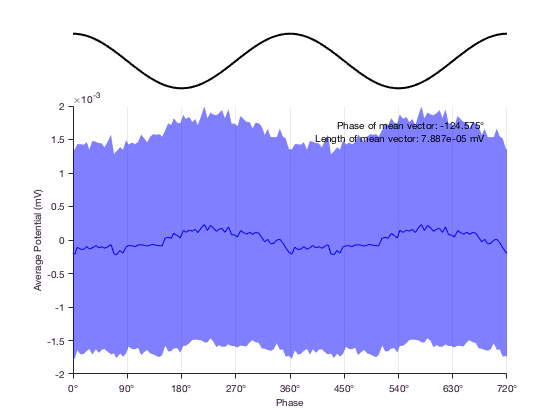

hlin = K_plotLinearPhaseWave(results,'ErrorBar','std');


hlin = K_plotLinearPhaseWave(results,'ErrorBar','sem');

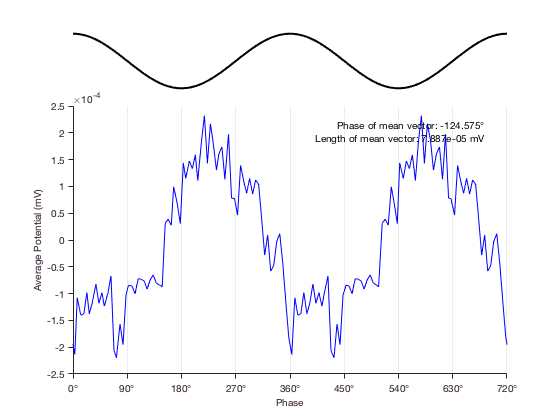


hlin = K_plotLinearPhaseWave(results,'errorbar','none');

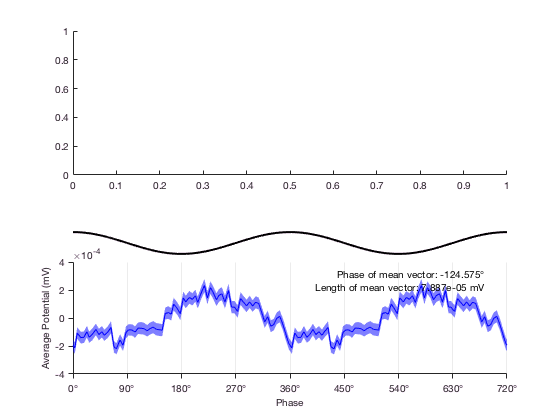

hlin = struct with fields:
          fig: [1×1 Figure]
         main: [1×1 struct]
          sub: [1×1 struct]
    titlepane: []
          txt: [1×1 Text]


figure
ax(1) = subplot(2,1,1);
ax(2) = subplot(2,1,2);

hlin = K_plotLinearPhaseWave(ax(2),results)

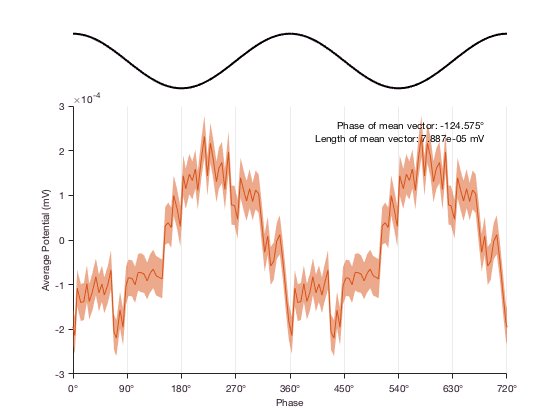

hlin = K_plotLinearPhaseWave(results,'Color',defaultPlotColors(2));


hlin = K_plotLinearPhaseWave(results,'XGrid','on');

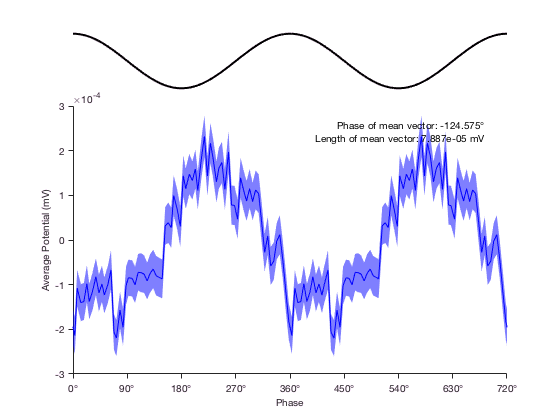


hlin = K_plotLinearPhaseWave(results,'XGrid','off');


hlin = K_plotLinearPhaseWave(results,'plotType','bar');


hlin = K_plotLinearPhaseWave(results,'plotType','line');

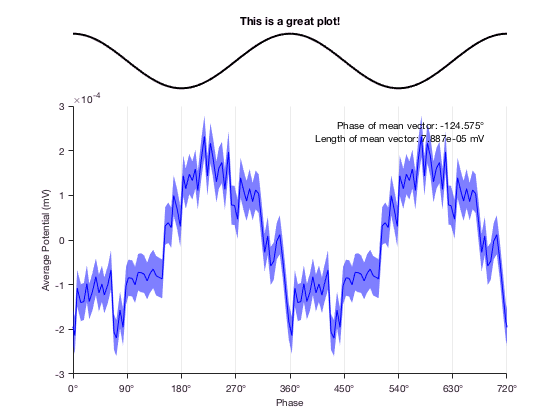


hlin = K_plotLinearPhaseWave(results,'Title','This is a great plot!');

hlin = K_plotLinearPhaseWave(results,'Color',defaultPlotColors(2));

# plot One neuron with `K_plotCircPhaseWave_one`

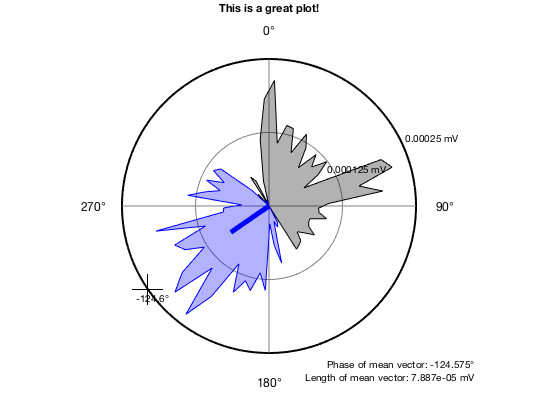


hcirc = K_plotCircPhaseWave_one(results,'Title','This is a great plot!');

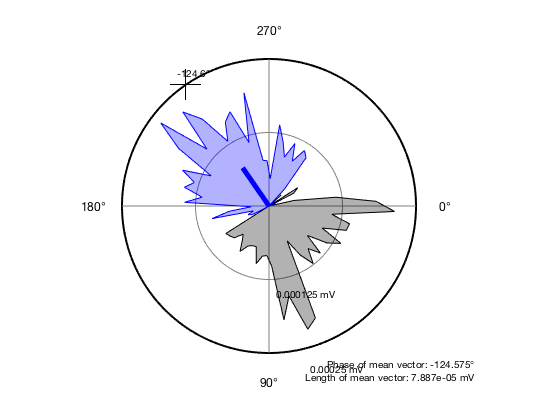

hcirc = K_plotCircPhaseWave_one(results,'ZeroPos','right');

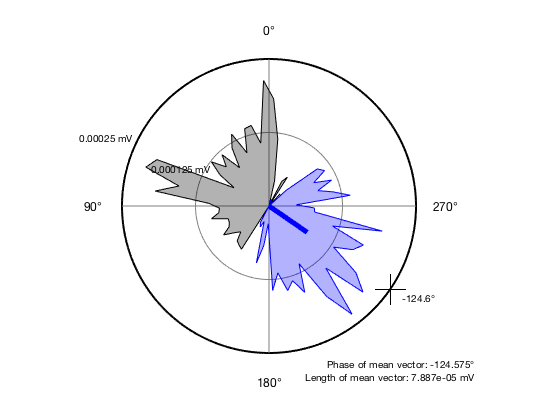

hcirc = K_plotCircPhaseWave_one(results,'Direction','anti');

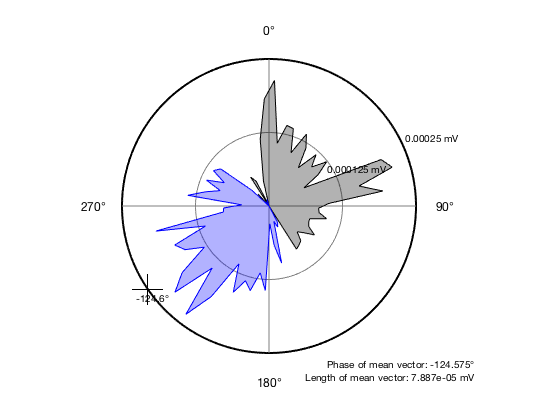

hcirc = K_plotCircPhaseWave_one(results,'ShowMeanVector',false);

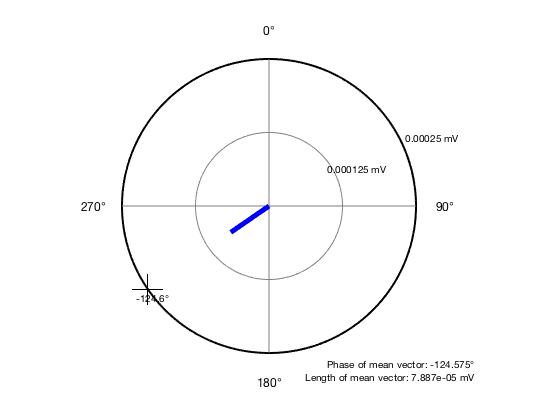

hcirc = K_plotCircPhaseWave_one(results,'ShowPatch',false);

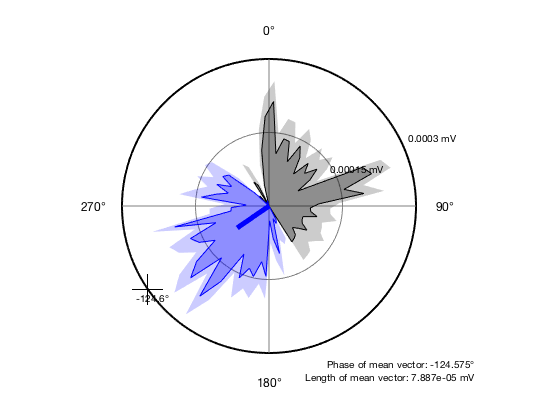

hcirc = K_plotCircPhaseWave_one(results,'ErrorRange','sem');

`std` is practically no use...

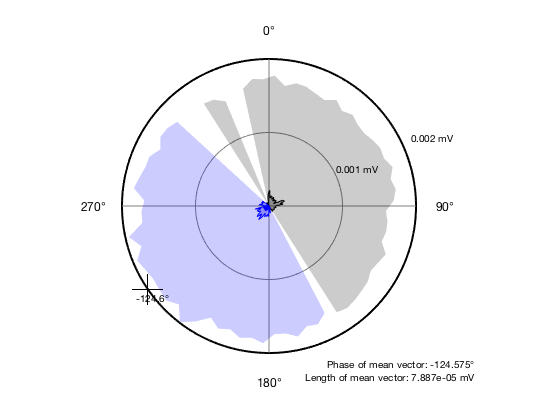

hcirc = K_plotCircPhaseWave_one(results,'ErrorRange','std');

hcirc = K_plotCircPhaseWave_one(results,'Title','This is a great plot!');

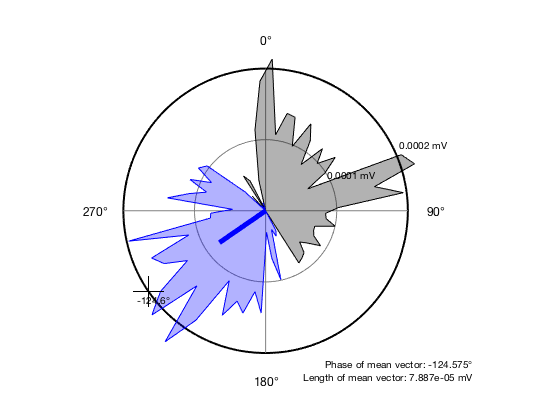

hcirc = K_plotCircPhaseWave_one(results,'Radius',0.0002);

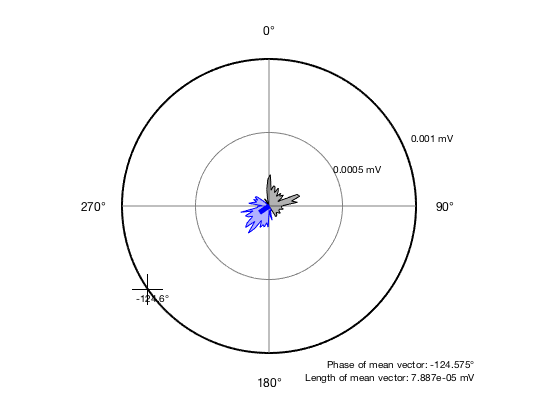

hcirc = K_plotCircPhaseWave_one(results,'Radius',0.0010);

# Group data

results = K_PhaseWave(bua1L.Data,eeg1L.Data,1024,1024,b,a,'randomization','none','HistBin',18);

results(2) = K_PhaseWave(bua2L.Data,eeg2L.Data,1024,1024,b,a,'randomization','none','HistBin',18);

results(3) = K_PhaseWave(bua3L.Data,eeg3L.Data,1024,1024,b,a,'randomization','none','HistBin',18)

results = 1×3 struct array with fields:
    binmean
    binstd
    binsem
    axrad
    meanvec
    bootstrap
    circshift


# K_plotLinearPhaseWave for group

ans = struct with fields:
          fig: [1×1 Figure]
         main: [1×1 struct]
          sub: [1×1 struct]
    titlepane: []
          txt: [1×1 Text]


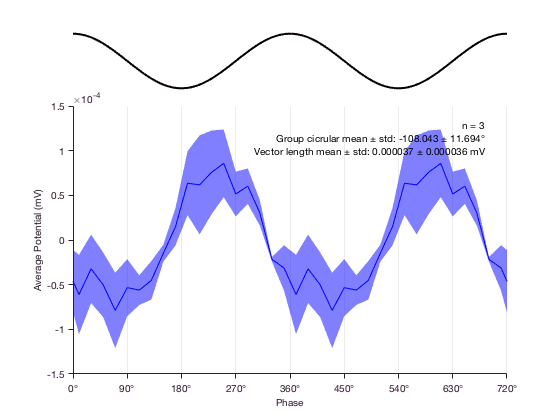

K_plotLinearPhaseWave(results)

ans = struct with fields:
          fig: [1×1 Figure]
         main: [1×1 struct]
          sub: [1×1 struct]
    titlepane: []
          txt: [1×1 Text]


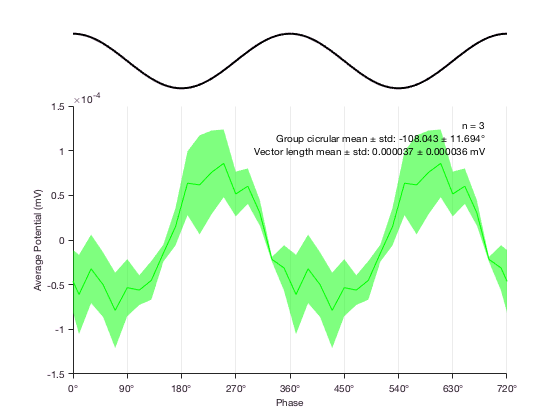

K_plotLinearPhaseWave(results,'Color','g')

ans = struct with fields:
          fig: [1×1 Figure]
         main: [1×1 struct]
          sub: [1×1 struct]
    titlepane: []
          txt: [1×1 Text]


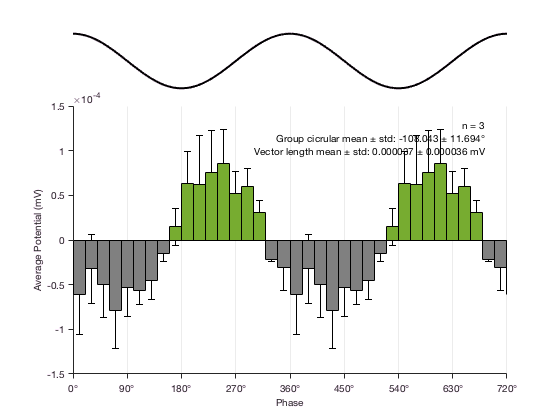

K_plotLinearPhaseWave(results,'PlotType','bar','Color',defaultPlotColors(5))

# K_plotLinearPhaseWave for group (surface)

ans = struct with fields:
          fig: [1×1 Figure]
         main: [1×1 struct]
          sub: [1×1 struct]
    titlepane: []
          txt: [1×1 Text]


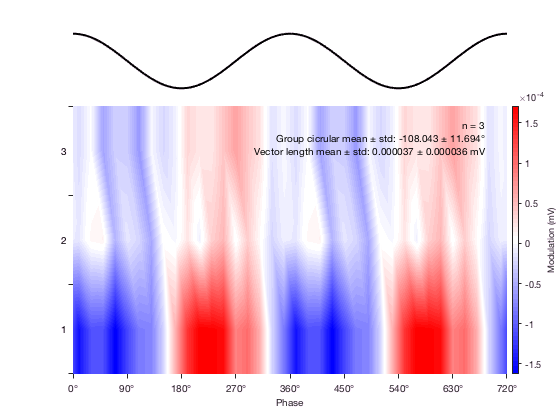

K_plotLinearPhaseWave(results,'PlotType','surface')

# K_plotCircPhaseWave_group

ans = struct with fields:
              fig: [1×1 Figure]
              axh: [1×1 Axes]
        outercirc: [1×1 Line]
        innercirc: [1×1 Line]
         vertline: [1×1 Line]
         horzline: [1×1 Line]
                t: [1×4 Text]
     txt_scalevec: [1×4 Text]
         histline: [1×1 Line]
        histpatch: [36×1 double]
    txt_scalehist: [1×2 Text]
          circles: [1×1 Line]
           vector: [3×1 Line]
             mark: [1×1 Line]
         synthvec: [1×1 Line]


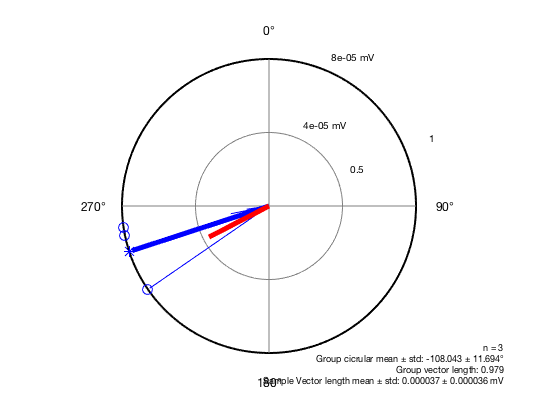

K_plotCircPhaseWave_group(results)

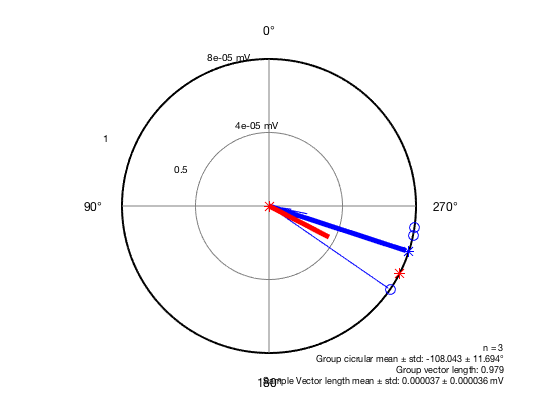

K_plotCircPhaseWave_group(results,'Direction','anti');

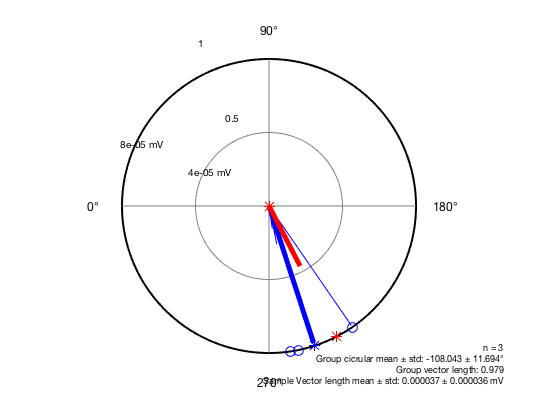

K_plotCircPhaseWave_group(results,'ZeroPos','left');

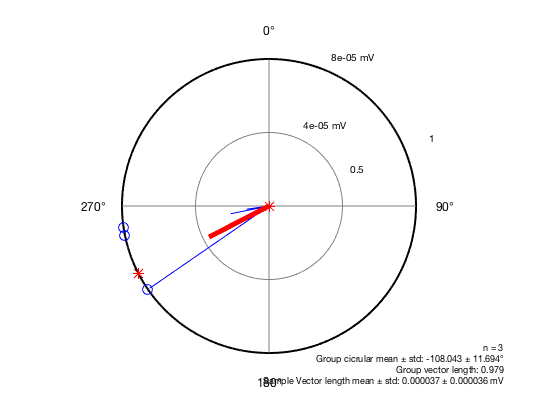

K_plotCircPhaseWave_group(results,'ShowGroupCirc',false);

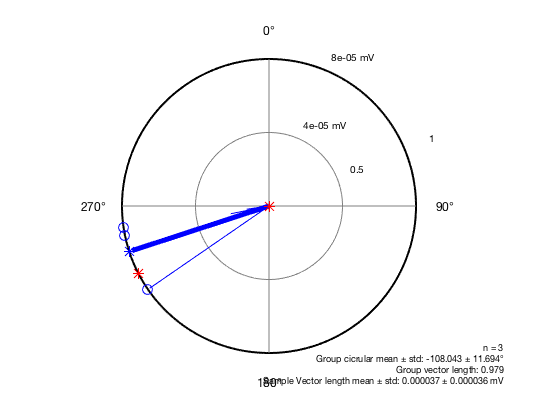

K_plotCircPhaseWave_group(results,'ShowGroupSyn',false);

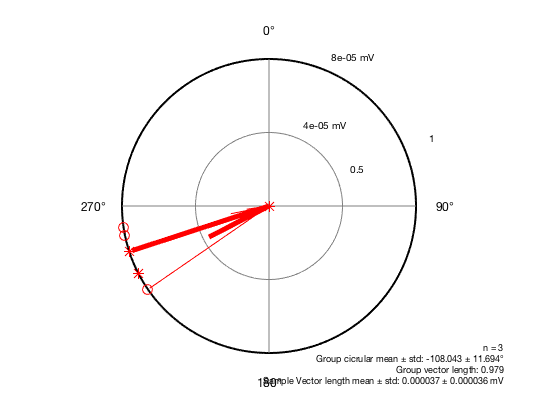

K_plotCircPhaseWave_group(results,'Color','r');

# with `Randomization` = `bootstrap`

 takes 0.8 min by Win

MacBook cannot cope

Wn = normalizedfreq([13 30],1024);
[b, a] = butter(3, Wn,'bandpass');
% fvtool(b,a,'Fs',newRate);
% xlim([0 5]);ylim('auto');
assert(isstable(b,a));


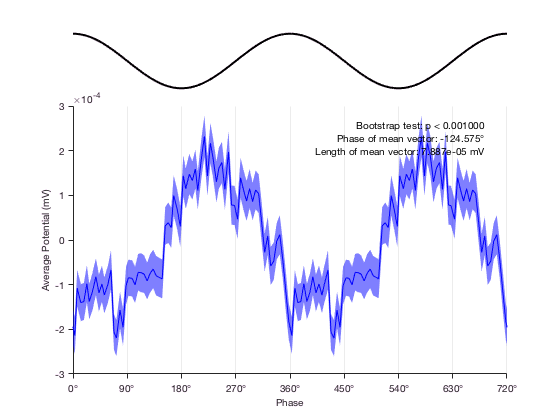

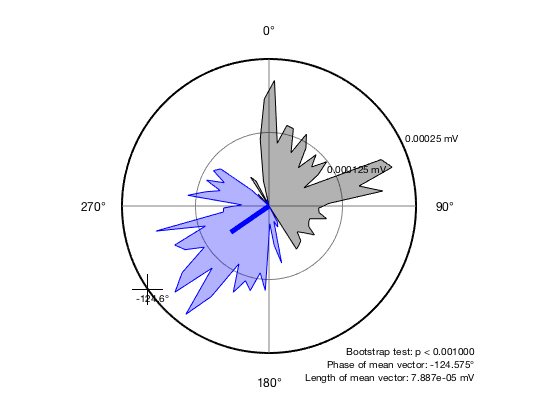

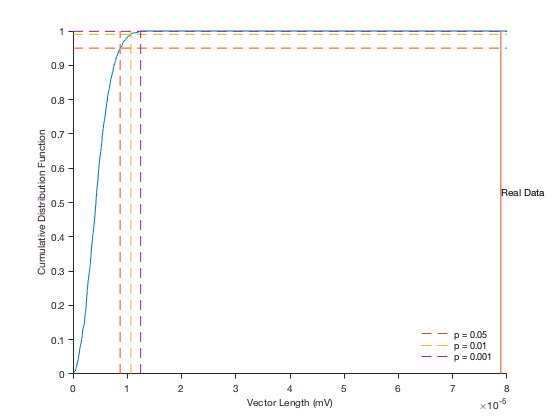

[results,handles] = K_PhaseWave(bua1L.Data,eeg1L.Data, 1024, 1024, b, a,...
    'plotLinear',true,'plotcirc',true,'randomization','bootstrap');

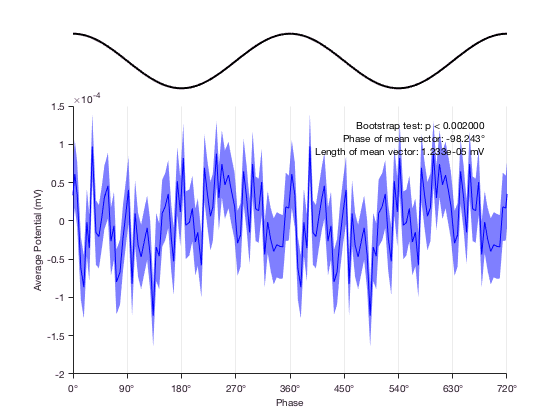

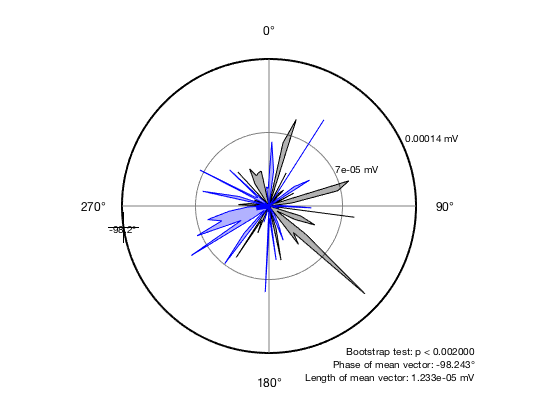

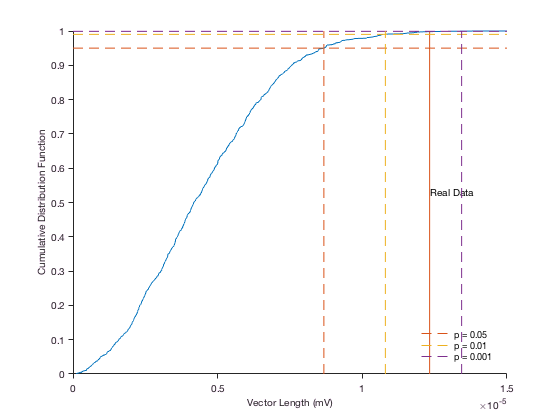

results(2)= K_PhaseWave(bua2L.Data,eeg2L.Data, 1024, 1024, b, a,...
    'plotLinear',true,'plotcirc',true,'randomization','bootstrap');

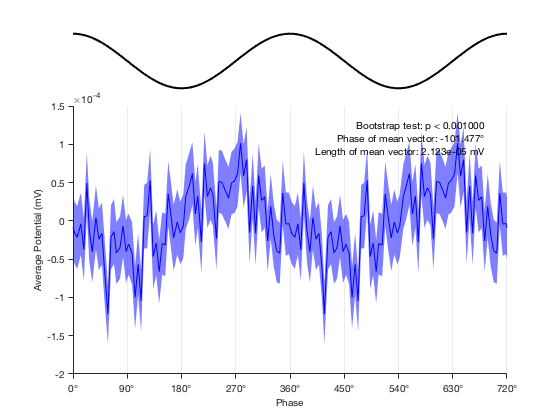

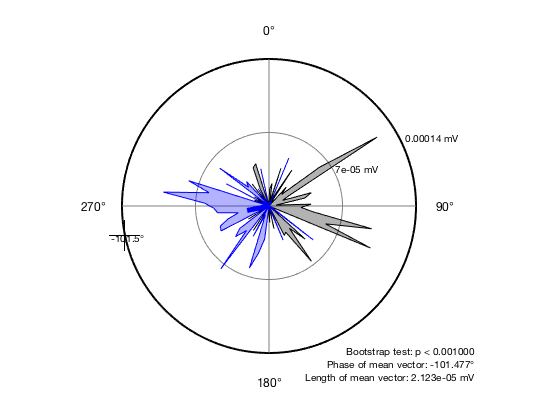

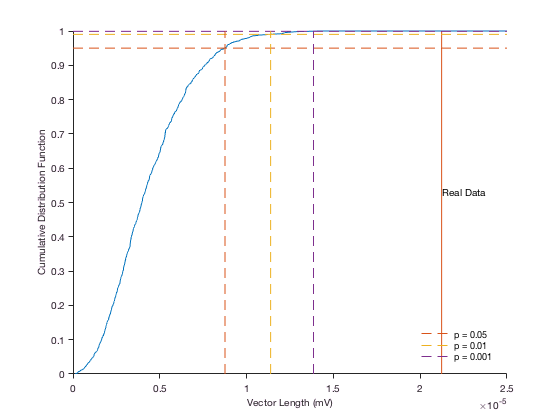

results(3) = K_PhaseWave(bua3L.Data,eeg3L.Data, 1024, 1024, b, a,...
    'plotLinear',true,'plotcirc',true,'randomization','bootstrap');

ans = struct with fields:
          fig: [1×1 Figure]
         main: [1×1 struct]
          sub: [1×1 struct]
    titlepane: []
          txt: [1×1 Text]


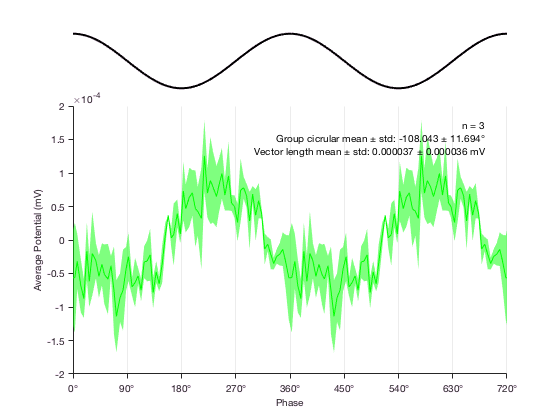

K_plotLinearPhaseWave(results,'Color','g')

Force group analysis even when `results` is scalar

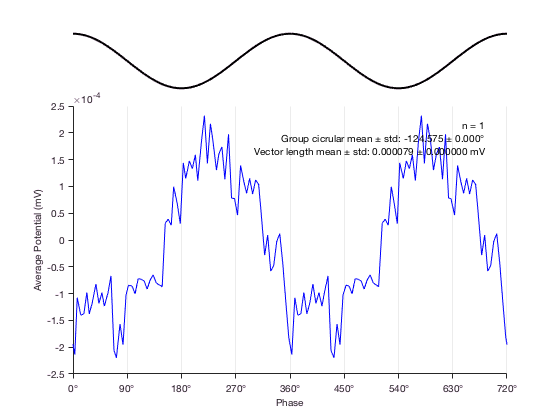

K_plotLinearPhaseWave(results(1),'AnalysisMode','group');

K_plotCircPhaseWave_group(results,'Title','What a great plot!');

# with `Randomization` = `circshift`

 takes 0.8 min by Win

MacBook cannot cope

Wn = normalizedfreq([13 30],1024);
[b, a] = butter(3, Wn,'bandpass');
% fvtool(b,a,'Fs',newRate);
% xlim([0 5]);ylim('auto');
assert(isstable(b,a));


Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.
***
***
*
***


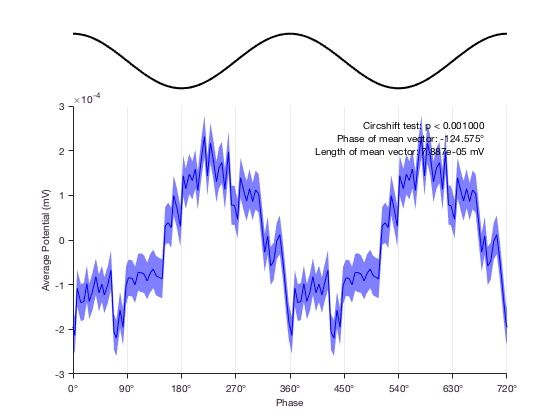

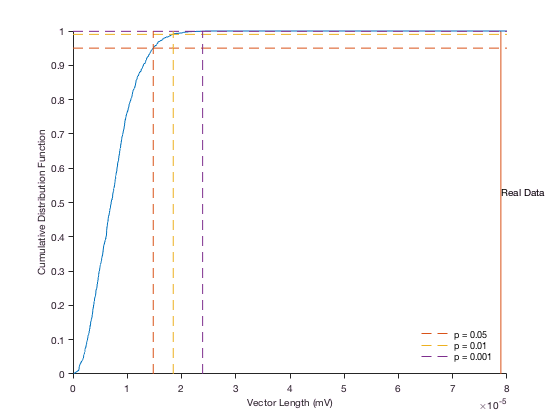

[results,handles] = K_PhaseWave(bua1L.Data,eeg1L.Data, 1024, 1024, b, a,...
    'plotLinear',true,'plotcirc',true,'randomization','circshift');

***
***
**
**


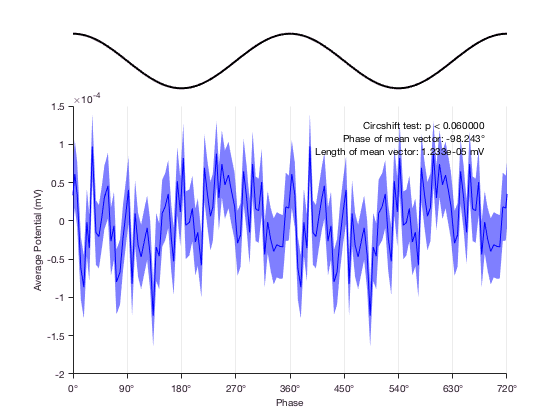

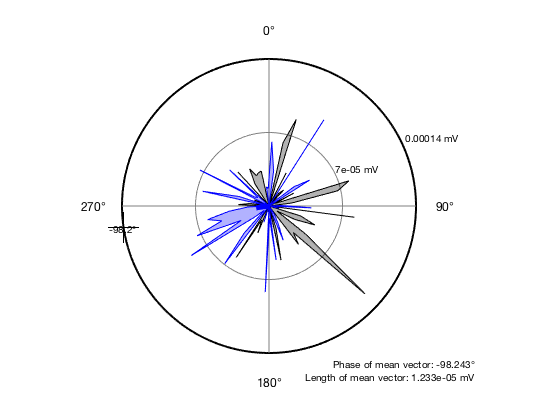

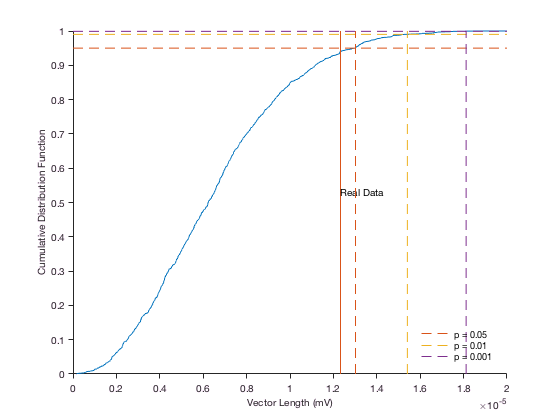

results(2)= K_PhaseWave(bua2L.Data,eeg2L.Data, 1024, 1024, b, a,...
    'plotLinear',true,'plotcirc',true,'randomization','circshift');

***
***
*
***


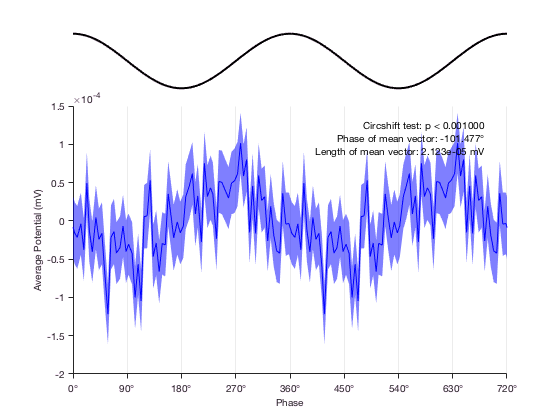

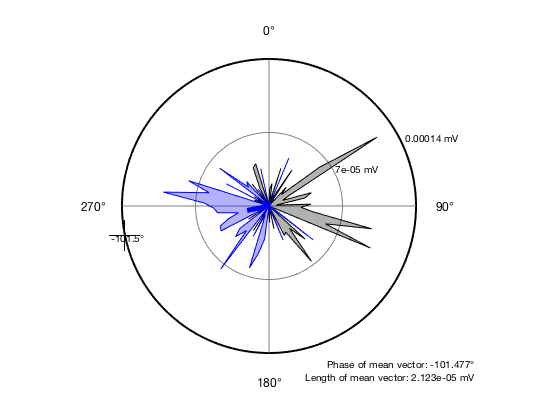

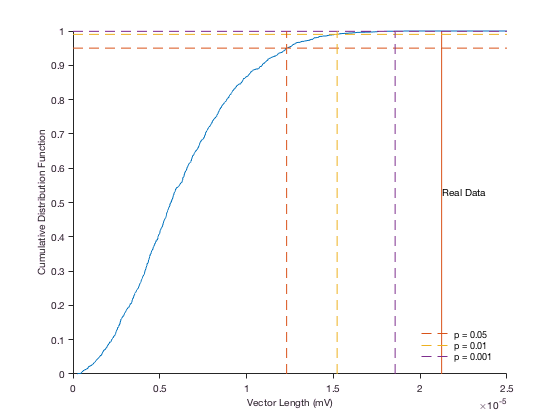

results(3) = K_PhaseWave(bua3L.Data,eeg3L.Data, 1024, 1024, b, a,...
    'plotLinear',true,'plotcirc',true,'randomization','circshift');

ans = struct with fields:
          fig: [1×1 Figure]
         main: [1×1 struct]
          sub: [1×1 struct]
    titlepane: []
          txt: [1×1 Text]


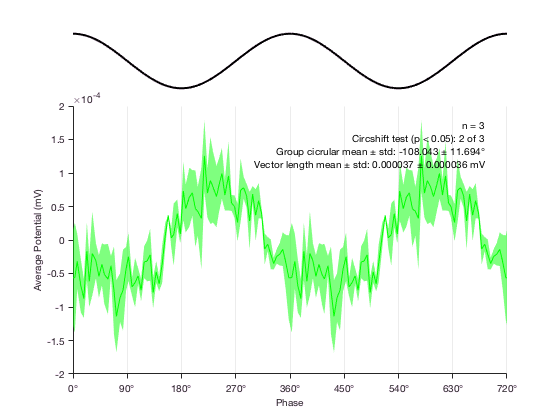

K_plotLinearPhaseWave(results,'Color','g')

Force group analysis even when `results` is scalar

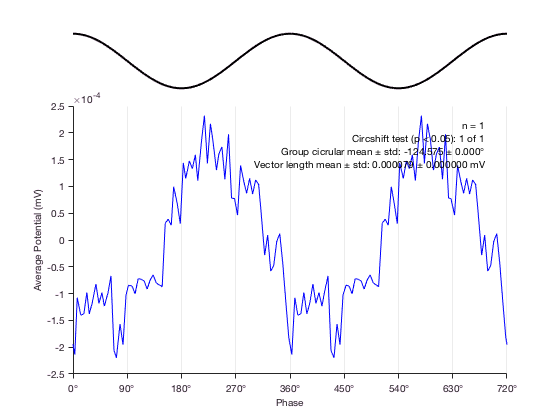

K_plotLinearPhaseWave(results(1),'AnalysisMode','group');

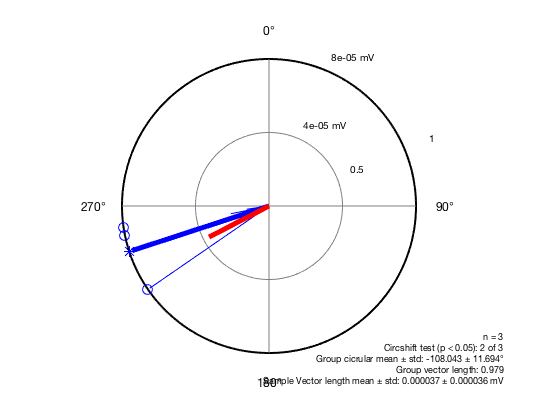

K_plotCircPhaseWave_group(results,'Title','What a great plot!');

# Local Functions

function [matname,eeg,wide] = local_getChan(chanSpec,S,I)

strongLFPBetaBZ = chanSpec.choose(...
    chanSpec.ismatnamematched(regexptranslate('escape', S(I,:).parent))...
    & (chanSpec.ischantitlematched(S(I,:).title) | chanSpec.ischan_EEG) ...
    & chanSpec.ismatvalid(chanSpec.ischan_probeA00h));


matname = strrep(strongLFPBetaBZ.MatNames{1}, '.mat','');

eeg = strongLFPBetaBZ.constructChan(1,'IpsiEEG');
wide = strongLFPBetaBZ.constructChan(1,2); % supposedly beta containig LFP channel

eeg.plotPowerSpectrum(1024, 2048, 2048); % very clear beta in the EEG channel!!!
wide.plotPowerSpectrum(1024, 2048, 2048); % very clear beta in the LFP channel!!!

eeg.plotCohere(wide, 1024, 2048, 2048); % good beta in spike-EEG coherence as well
end
%--------------------------------------------------------------------------
function [eegL,lfpL,buaL] = local_getEEGLFPBUA(eeg,wide)

eegL = eeg.resample(1024);

Wn = normalizedfreq(300,wide.SRate);
[b,a] = butter(5,Wn,'low');

% fvtool(b,a,'Fs',wide.SRate);
% close

lfp = wide;
lfp.Data = filtfilt(b,a,wide.Data);

lfpL = lfp.resample(1024);
lfpL.Data = lfpL.Data - mean(lfpL.Data);% mean subtraction

Wn = normalizedfreq(300,wide.SRate);
[b,a] = butter(5,Wn,'high');
high = filtfilt(b,a,wide.Data);

thre = std(high)*3;
clear b a
buaL = wide.getBUA('wideband thresholding',3,thre,...
    'plotTriggered','on','plotwith','averageonly','spikewindow',[2,3],...
    'meanadjustment','global');

buaL.plotPowerSpectrum(1024,2048,2048);
ylim([0 5e-8])
xlim([0 100])

buaL.plotCohere(eegL,1024,2048,2048);
ylim([0 1])
xlim([0 100])

end